# load the files

clearvars;
addpath(genpath('./drtoolbox'))
addpath(genpath('./Brewermap'))
addpath(genpath('./tsne'))
addpath(genpath('./DiffusionMap'))
addpath(genpath('./DynamicalAnalysis'))
addpath(genpath('./GeneAnalysis'))
addpath(genpath('./Visualization'))

## generating simulation data

rng(1)
%{
lambda_0 = -3;
x_0 = 2.1038;
par.T_max = 6;
par.dt = 1e-5;
sigma = 40;
[x_out, t_out, lambda_out] = generating_simulation_data (@V_potential, sigma, x_0, lambda_0, par);
figure;
plot(t_out,x_out)


sample_id = abs(t_out-3.257)<0.02;
x_out_sample = x_out(sample_id);
t_out_sample = t_out(sample_id);

figure;
plot(t_out_sample,x_out_sample)

N_cell = length(x_out_sample);
sub_sample_id = 1:2:N_cell;
N_cell = length(sub_sample_id);
data = x_out_sample(sub_sample_id )';
true_labs = t_out_sample (sub_sample_id );


%save 

save('saddlenode_new.mat','x_out_sample','t_out_sample','sample_id','x_out','t_out','lambda_out','sigma','data');
%}

## Load the Data and Estimate Number of Clusters by EPI

load saddlenode.mat
% parameter and option settings
par.choice_distance = 'cosine';
out = EstClusterNum(data,par);

Computed P-values 500 of 2000 datapoints...
Computed P-values 1000 of 2000 datapoints...
Computed P-values 1500 of 2000 datapoints...
Computed P-values 2000 of 2000 datapoints...
Mean value of sigma: 2.9802e-08
Minimum value of sigma: 2.9802e-08
Maximum value of sigma: 2.9802e-08


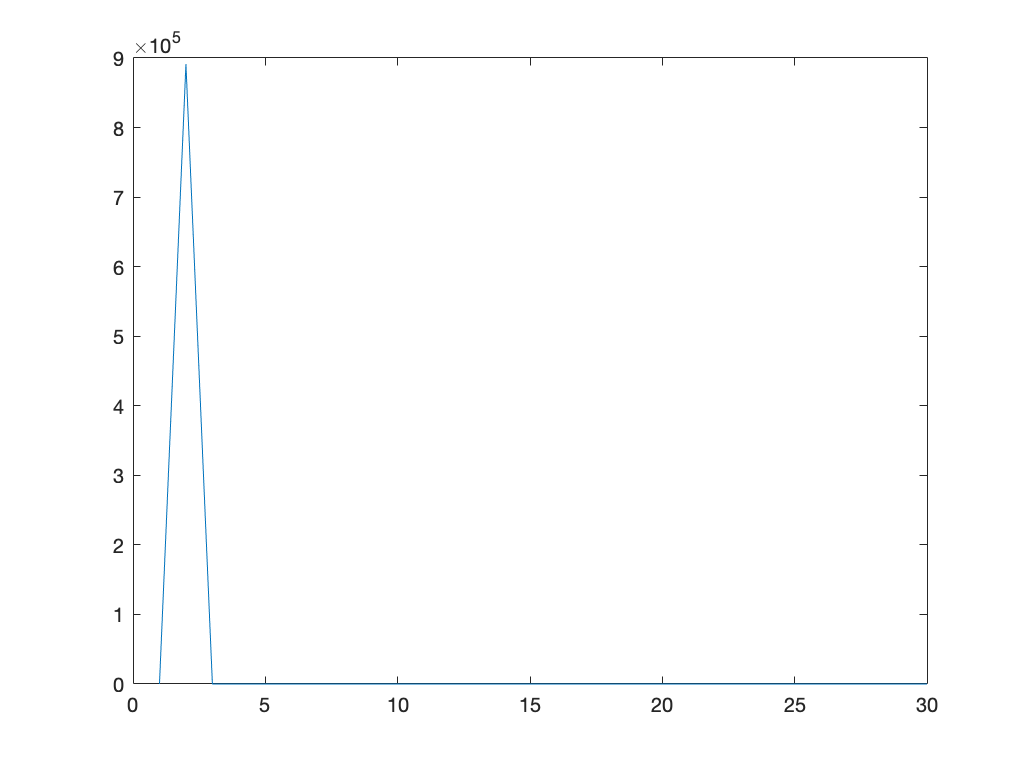

plot(out.ratio(1:30))

## Dynamical Analysis and Output

tic;
par.perplex = 800;
par.K_cluster = 2;
par.trials = 20;
Output = DynamicalAnalysis (data, par);

Computed P-values 500 of 2000 datapoints...
Computed P-values 1000 of 2000 datapoints...
Computed P-values 1500 of 2000 datapoints...
Computed P-values 2000 of 2000 datapoints...
Mean value of sigma: 2.9802e-08
Minimum value of sigma: 2.9802e-08
Maximum value of sigma: 2.9802e-08


J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

J_new = 0.0020

E_best = 0

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1       0.00271942                      7.03e-07

Optimization completed: The final point is the initial point.
The first-order optimality measure, 7.028373e-07, is less than
options.OptimalityTolerance = 1.000000e-06.

Elapsed time is 1.415490 seconds.


toc;

Elapsed time is 1.437111 seconds.



class_order = Output.class_order;
rho_class = Output.rho_class;
perm_class = Output.perm_class;
P_perm = Output.P_perm;
P_hat = Output.P_hat;
P_appr_perm = Output.P_appr_perm;
P_rho = Output.P_rho;
labs_perm = Output.labs_perm;
data_perm = Output.data_perm;
mu_hat = Output.mu_hat;
k = Output.k;
H = Output.H;

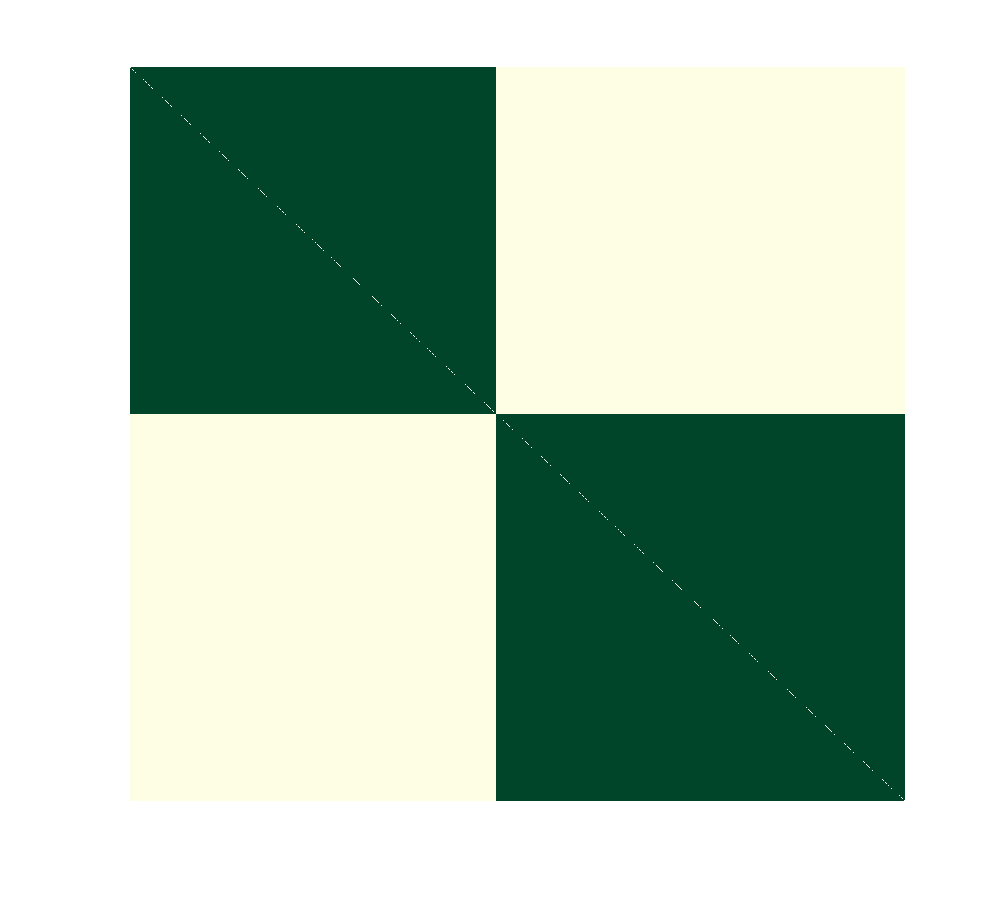

max_P = 0.2* max(max(P_rho));
c_lim = [0 max_P];
cmp = 'ylgn';

figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_perm);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)

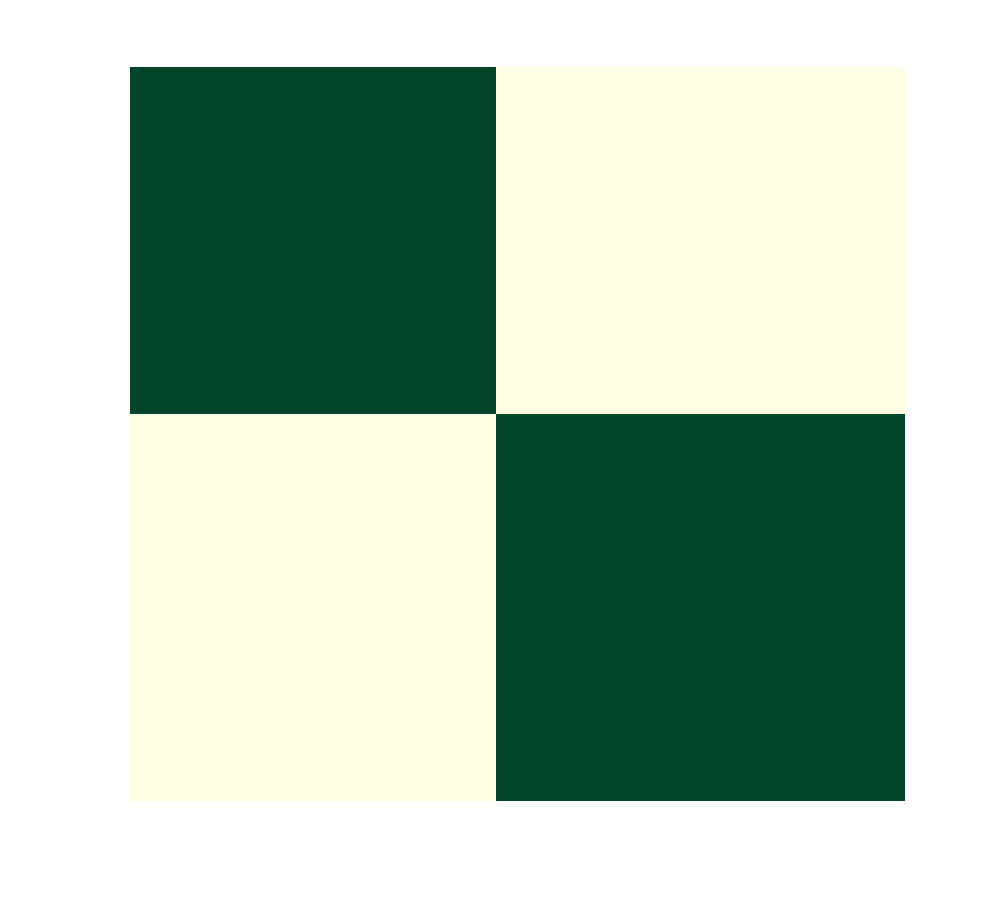

%colorbar;


figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_appr_perm);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)

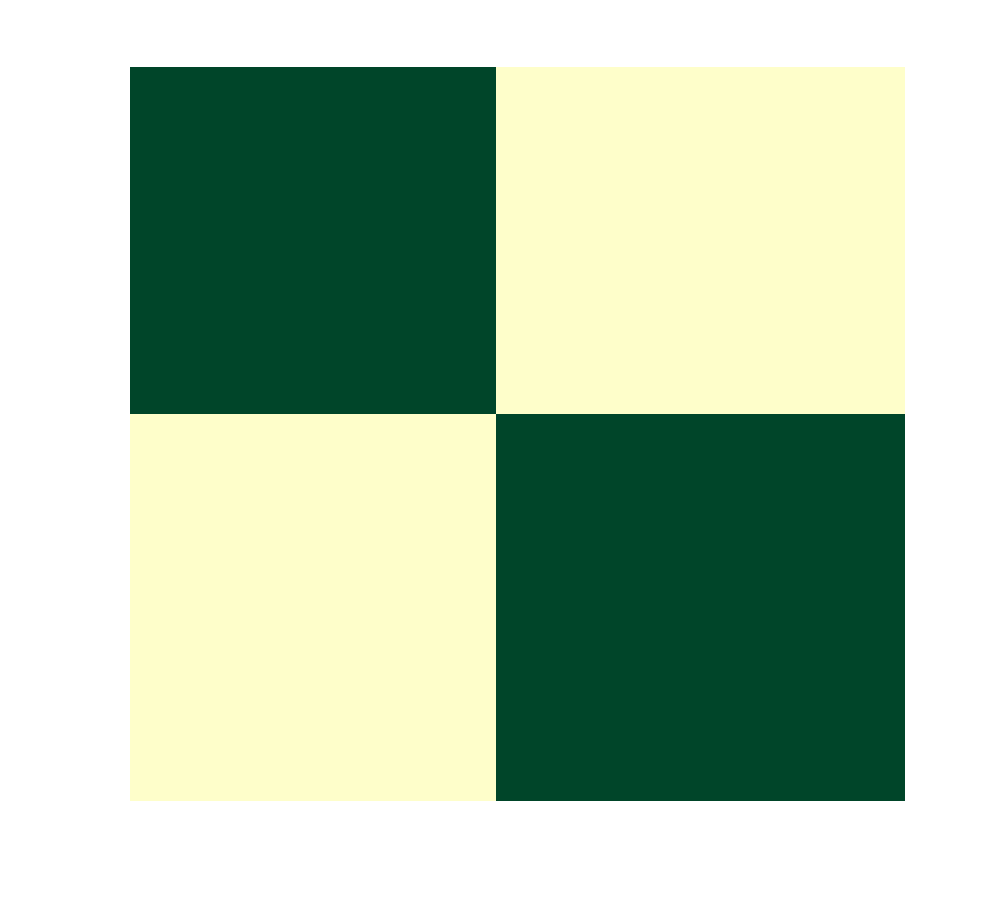

%colorbar;


figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_rho);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)
%colorbar;
box off

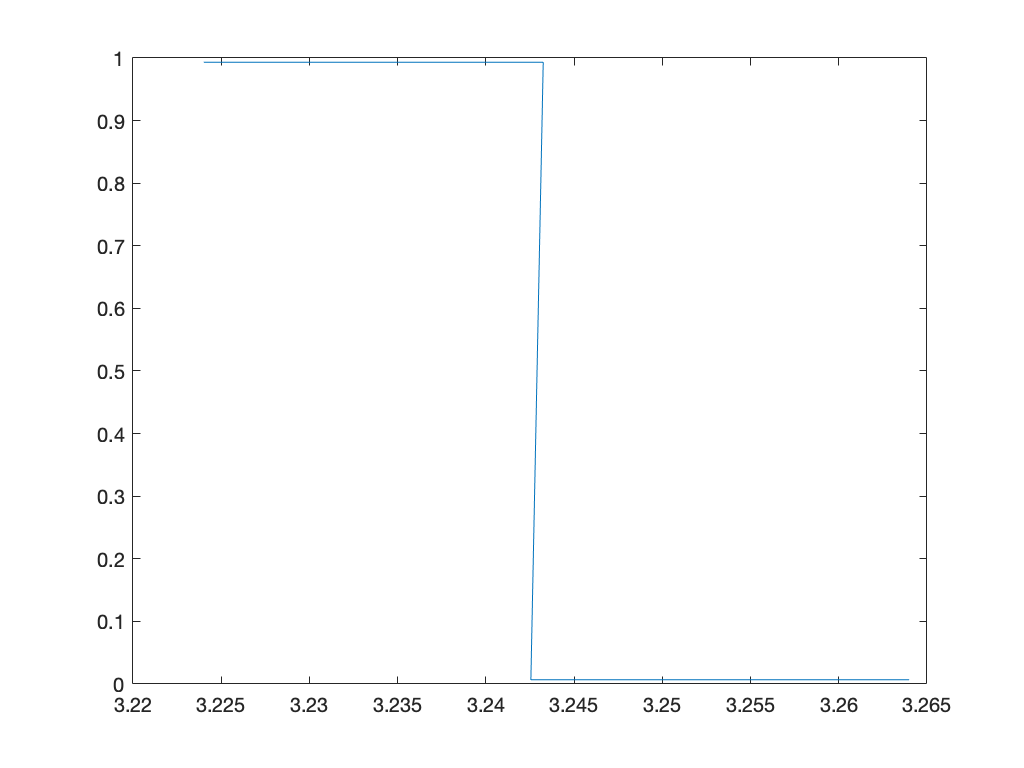


figure;
plot(labs_perm, rho_class(:,1))

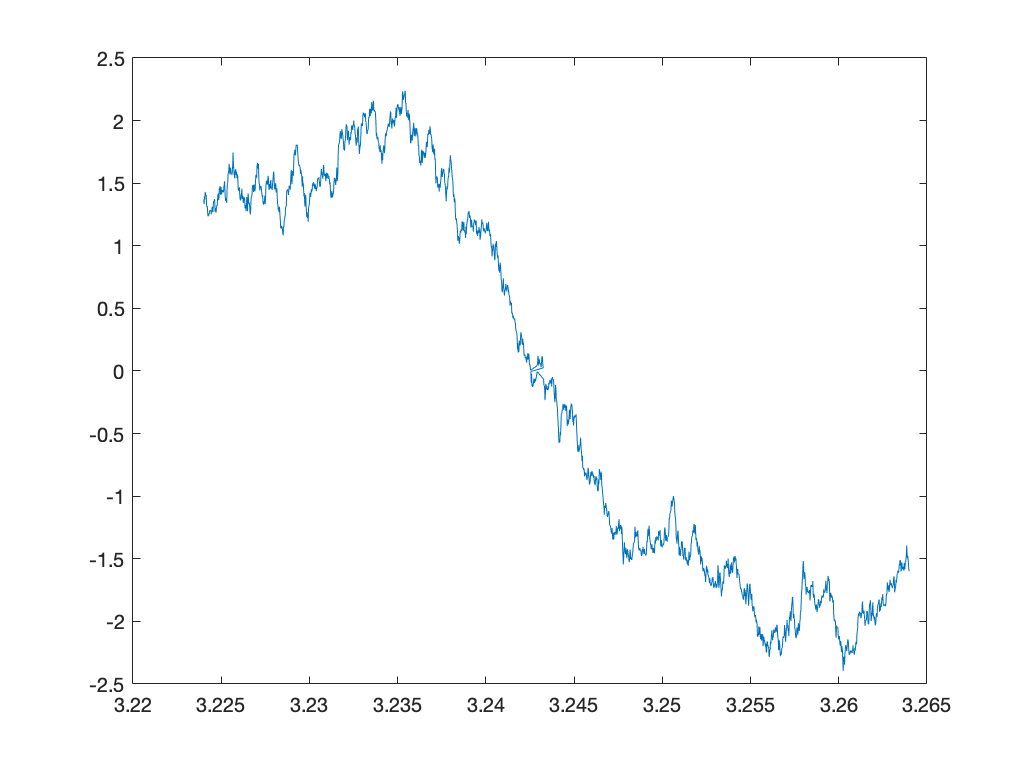


figure;
plot(labs_perm, data_perm)